# MPC Distrubance Rejection

## System

mcart = 0.493;
mpend = 0.312;
Ipend = 0.00024;
l = 0.04;
f = 0.01;
kt = 0.11;
R = 10;
r = 0.0335;
g = 9.81;

%% State Space
A = [0 1 0 0;
    0 (-(Ipend + mpend*l^2)*f)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend^2*g*l^2/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0;
    0 0 0 1;
    0 -mpend*l*f/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend*g*l*(mcart+mpend)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0];
B = [0; (Ipend+mpend*l^2)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2);
    0; mpend*l/(Ipend*(mcart+mpend)+ mcart*mpend*l^2)];

## LQR

lqr_weight = [100 1 1e6 1e2];
Q_lqr = diag(lqr_weight);
R_lqr = 1;
C= [1 0 0 0];
D = 0;
K=lqr(A,B,Q_lqr,R_lqr);

## Closed Loop System

A_cl=A-B*K;
B_cl=B;
plant=ss(A_cl,B_cl,C,D);
PP = c2d(plant,0.1,'zoh');
A=PP.A;
B=PP.B;
C=PP.C;

## Augmented State Space 

state_n = size(A, 1);

A_new = [A zeros(state_n,1); C 1];
B_new = [B zeros(state_n,1); 0 -1];
C_new = [C 0; zeros(1,state_n) 1];

input_n = size(B_new, 2);

## MPC Formulation

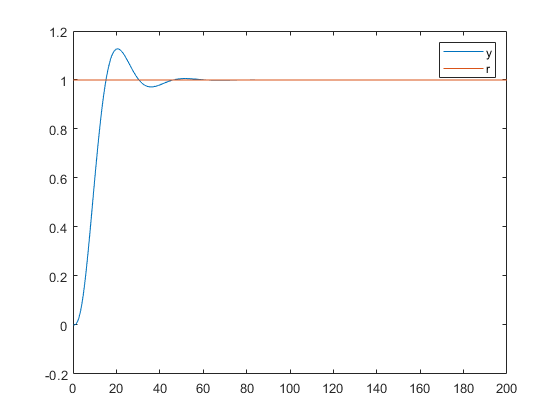

N = 2;
R = diag([12.5; 1]); % Ubar = [control; reference]
Q = diag([1; 1]);  % output = [position; integral of error]
Qbar = blkdiag(Q,Q);
Rbar = blkdiag(R,R);
Tbar = [C_new*A_new;C_new*A_new^2];
Sbar = [C_new*B_new zeros(2,2);C_new*A_new*B_new C_new*B_new];
H = 2*(Rbar+Sbar'*Qbar*Sbar);
warning('off','all')
options = optimoptions('quadprog');
options.Display = 'none';

G = [tril(ones(N*input_n));-tril(ones(N*input_n))];
S = zeros(4*input_n,5);

iter = 2000;
r = 1*ones(iter,1);
Xact = [];
Uopt = [];
X = [0;0;0;0;0];
U = [0; r(1)];
eps = 0.0000;

U_disturb = [0; 0];
X_disturb = [0; 0; 0; 0; 0];
for ii = 1:iter-1
    Xact(:,ii) = X;
    Rbarref = [r(ii);0;r(ii);0];
    f = 2*(X'*Tbar'*Qbar*Sbar-Rbarref'*Qbar*Sbar); 
    W = [12;r(ii)+eps;12;r(ii)+eps; 12;-r(ii)+eps;12;-r(ii)+eps];
    
    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);
    Uopt(:,ii) = [-Z(1,:); r(ii)] + U_disturb;
    U = Uopt(:,ii);

    X = A_new*X+B_new*U + X_disturb;
end
Xact(:,ii+1) = X;

%% Plotting
y=C_new*Xact;
plot([1:iter].*0.1,y(1,1:iter),[1:iter].*0.1,r(1:iter))
legend('y','r')

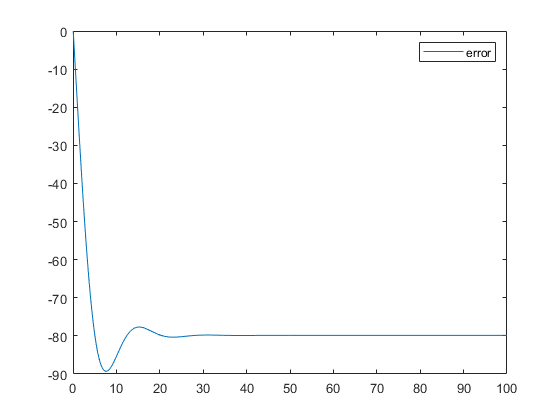

plot([1:iter].*0.05,y(2,1:iter))
legend('error')

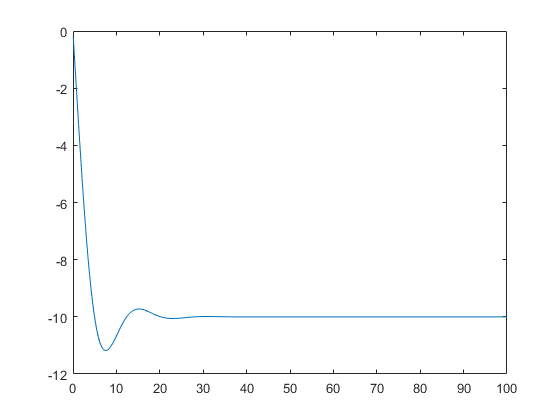

plot(0.05*[1:iter-1], Uopt(1, 1:iter-1))